Wrocław 14.04.2021

Aleksander Kudyba

245084

# Ruchliwość nośników w domieszkowanych półprzewodnikach w zależności od temperatury

- Ze względu na zmianę temperatury mamy do czynienia z dwoma typami rozpraszania się nośników. Pierwszym - spowodawanym drganiami sieci krystalicznej, czyli rozpraszaniem na fononach i drugim - rozpraszaniem na zjonizowanych domieszkach. 

Można oszacować wpływ  rozpraszania na fononach na ruchliwość nośników, używając związku pomiędzy ruchliwością i średnim czasem pomiędzy zderzeniem nośnika z centrum rozproszeniowym - $\tau$ oraz zależności średniej drogi między tymi zderzeniami a $\tau$. Przy tym zakładamy, że średnia droga swobodna jest odwrotnie proporcjonalna do prawdopodobieństwa rozproszenia na fononach, czyli do temparatury ($l\sim T^{-1}$) Uzyskujemy w ten sposób stosunek ruchliwości od temperatury dla tego typu rozproszeń.

$\mu=\frac{e}{m^*}\tau$,


$$l\sim\tau T^{\frac{1}{2}}$$



$$\mu_{temp}\propto \tau_{temp} \sim lT^{-\frac{1}{2}}\sim T^{-\frac{3}{2}}$$


Drgania sieci krystalicznej zmniejszają, więc ruchliwość nośników proporcjonalnie do $T^{-\frac{3}{2}}$. 

- W przypadku rozpraszania na zjonizowanych domieszkach, można przyjąć założenie, że jeśli nośnik ma się rzoproszyć musi być wystarczjąco długo w polu zjonizowanej domieszki. 

Wraz z temperaturą jednak średnia prędkość swobodna nośnków wzrasta i rozproszenie takie jest co raz mniej prawdopodobne. Nośnik więc musi być wystarczająco blisko jonu by energia termiczna mogła być prównywalna z energią elektrostatyczną. Mamy więc warunek,

$\frac{Ze^2}{4\pi \varepsilon r_s}=\frac{3}{2}k_B T$,

co daje nam promień efektywnego oddziaływania,


$$r_s=\frac{Ze^2}{6\pi k_B T}$$


i przekrój efektywnego oddziaływania,


$$S_s = r_s^2\pi=\frac{1}{\pi}(\frac{Ze^2}{6\varepsilon k_B T})$$


By wykorzystać ten wynik musimy założyć, że przekrój ten jest równoważny mocy rozpraszania jonu. Zakładając także, że średnia droga swobodna jest odwrotnie proporcjonalna do tej mocy. Możemy porównać,

$\mu_{domieszek}\propto \tau_{domieszek}=lT^{-\frac{1}{2}}\sim S_s^{-1}T^{-\frac{1}{2}}\sim T^{\frac{3}{2}}$,

uzyskując stusunek ruchliwości od temperatury dla rozpraszania na zjonizowanych domieszkach. By uzyskać jadną krzywą ruchliowści od temperatury, można skorzystać z zsaday Matthiessena: 

$\frac{1}{\mu} = \frac{1}{\mu_{temp}} + \frac{1}{\mu_{domieszek}}$.

Trzeba jednak pamiętać, że tak sumowana ruchliwość może dać jedynie ogólny zarys zjawiska, stąd dla wyżej omawianego przypadku ta zasada nie jest spójna. Ponieważ prawdopodobieństwo rozproszenia na zjonizowanej domieszce jest zależne od prawdopodobieństwa rozproszenia na fononach, nie możemy ich po prostu dodać do siebie w ogólności. 

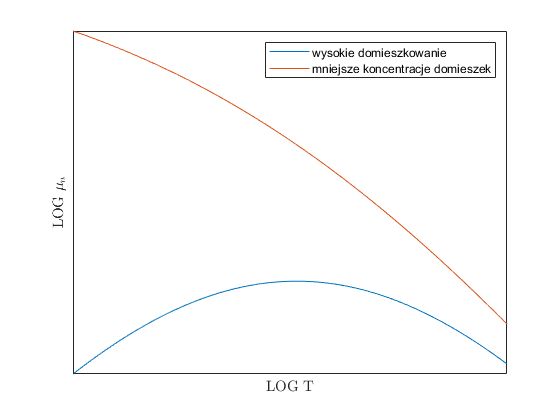

T = linspace(0.65,1.5,1e5);
y_th = 1./T.^(-3/2); %thermal scattering
y_ii = 1./T.^(3/2);  %ionized impurity scattering
offset = 1; %doping concentration offset
dop_y_ii = 1./(T.^(3/2)+offset);
y = y_th + y_ii;
g = y_th + dop_y_ii;
Y = 1./y;
G = 1./g;

loglog(T,Y,T,G);
ylabel('LOG $\mu_n$','Interpreter','latex')
xlabel('LOG T','Interpreter','latex')
xticks([]);
yticks([]);
legend('wysokie domieszkowanie', 'mniejsze koncentracje domieszek');